# Lista AB2.1

## Questão 1

z = tf('z')


z =
 
  z
 
Sample time: unspecified
Discrete-time transfer function.



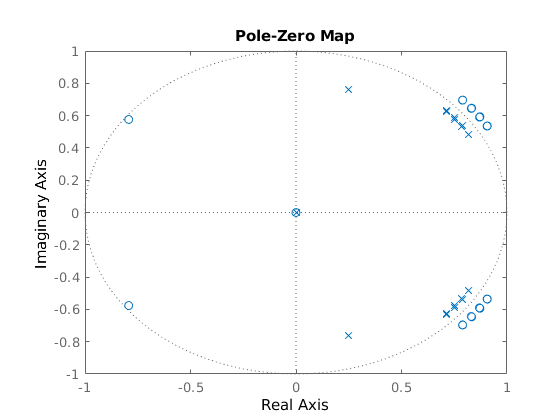


prod_num = 1;
prod_den = 1;
for k = 1:4
    c_k = 0.95*exp(j*(.15*pi+.02*pi*k));
    prod_num = prod_num * ((conj(c_k) - z^-1) * (c_k - z^-1))^2;
    prod_den = prod_den * ((1 - c_k*z^-1) * (1 - conj(c_k)*z^-1))^2;
end

num = (1 - .98*exp(j*.8*pi)*z^-1) * (1 - .98*exp(-j*.8*pi)*z^-1) * prod_num;
den = (1 - .8*exp(j*.4*pi)*z^-1) * (1 - .8*exp(-j*.4*pi)*z^-1) * prod_den;

H = num/den;

%% Diagrama de Polos e Zeros
pzmap(H);

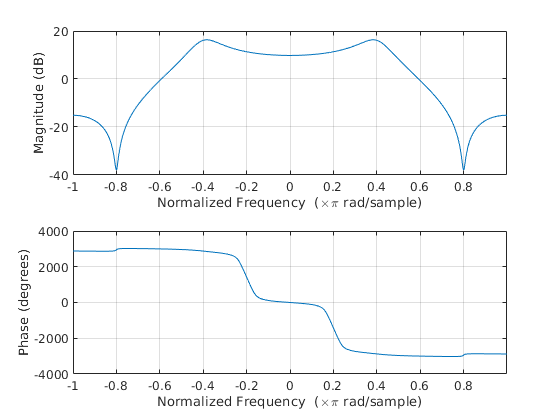


%% Respostas de Magnitude, Fase e Atraso de Grupo.
f = -pi:0.00001:pi;
[num,den] = tfdata(H,'v');

freqz(num,den,f);

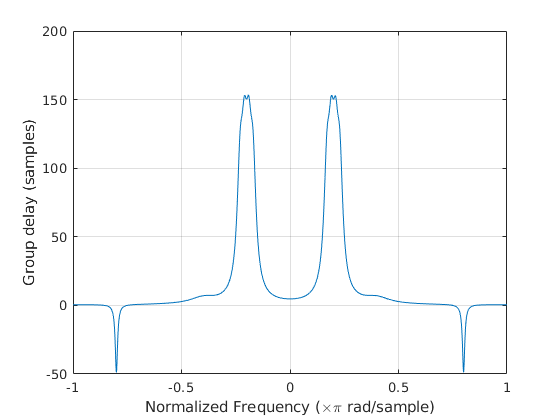

grpdelay(num,den,f);

## Questão 2

É notável que $x\left\lbrack n\right\rbrack$ corresponde à concatenação dos $x_1 \left\lbrack n\right\rbrack$, $x_2 \left\lbrack n\right\rbrack$ e $x_3 \left\lbrack n\right\rbrack$.

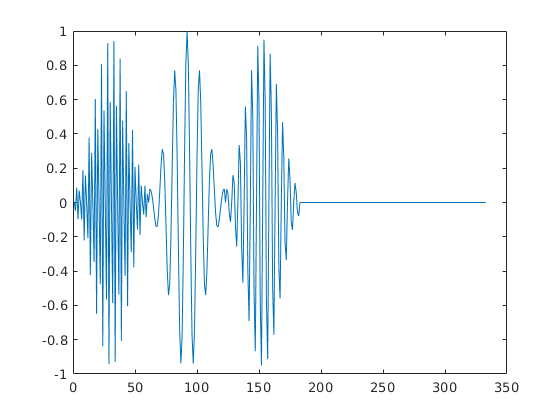

M = 60;
n = 0:60;
w = .54 - .46 * cos(2*pi*n/M);

x_1 = w .* cos(.2*pi*n);
x_2 = w .* cos(.4*pi*n - pi/2);
x_3 = w .* cos(.8*pi*n + pi/2);

x = [x_3 x_1 x_2 zeros(1, 150)];

%% Sinal x[n]
sample_number = 1:length(x);
plot(sample_number, x)

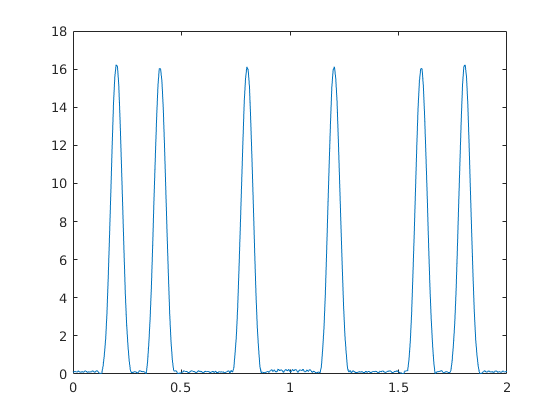


%% Magnitude da Transformada de Fourier de x[n]
y = fft(x);
sample_freq =linspace(0,2,length(y));
plot(sample_freq, abs(y));

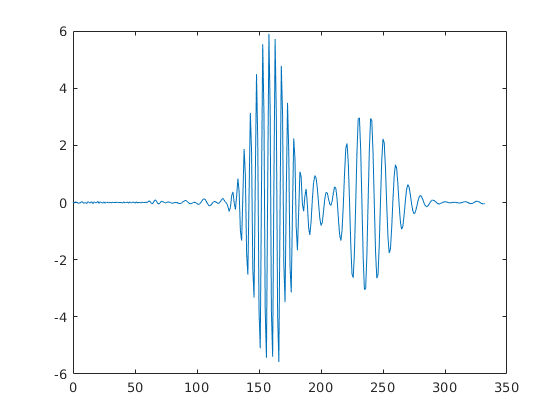


%% Alimentando sistema H com sinal de entrada x
[out, t] = lsim(H, x);
plot(t, out);